# Generating Features from the Flights Dataset

## Introduction

In this reading you will practice generating new features from the original variables provided in the Flights Dataset. There are many questions you could ask about this data, and therefore there are a near limitless number of possible new and useful features to generate. This Live Script contains a few examples that cover the three general approaches for feature generation:

- Discretization

- Summarizing Groups

- Transforming Variables

To begin, you must first...

## Import the Flights Dataset

Import the flights and airports .csv files. The flights data is assigned the temporary name, `flightsOriginal`, so that if you change the table you can always return to the original version.

flightsOriginal = importFlightsData("flightsFeb.csv"); % Import one month of data
airports = readtable("airports.csv"); % Import the airports data

## Discretization

There are many ways to generate new features by discretizing existing variables. Here are a few examples:

### Discretize datetimes by day of the month

How are the flights distributed across each day in a month? Are some days more popular than others?

To find out, extract the day of the month from the datetime variable.

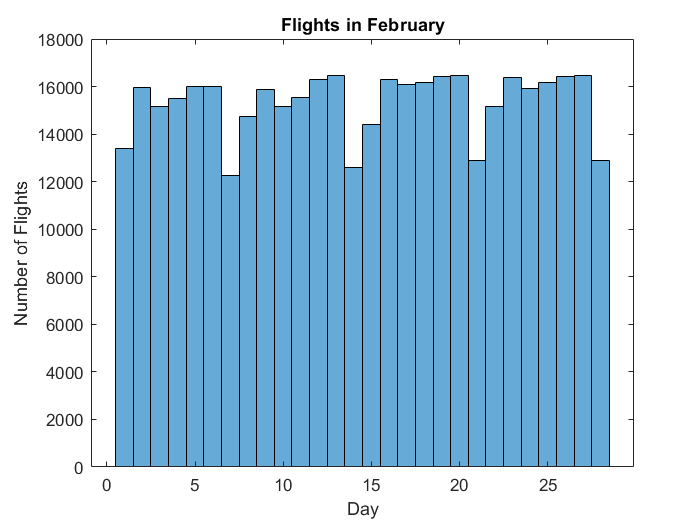

% Start with original flights dataset
flights = flightsOriginal;

% Create a new feature by discretizing by day of month
flights.DAY_OF_MONTH = day(flights.SCHEDULED_DEPARTURE_TIME);

% Plot a histogram of the results
histogram(flights.DAY_OF_MONTH);
title("Flights in February")
xlabel("Day")
ylabel("Number of Flights")

The result shows a clear 7-day cycle of a low-trafficked day, starting on the 1st (for the default month of February). But which day of the week is it? To find out...

### Discretize numbers

Of course, you can also discretize regular numeric variables too.

Now that you already know the weekly pattern for the number of flights per day, do you think the number of delayed flights also follows the same trend?

You can use the `discretize` function to create a new feature that categorizes each flight as being either "On Time" or "Delayed".

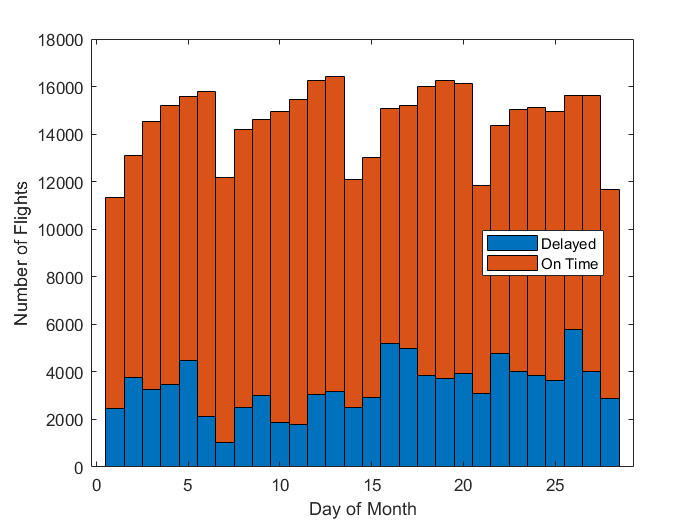

% Create a new feature, with flights arriving <= 15 minutes late counted as "On Time"
% While flights that are > 15 minutes late are counted as "Delayed"
flights.DELAYED = discretize(flights.ARRIVAL_DELAY,[-inf,15,inf],"categorical",["On Time", "Delayed"]);

% Take only the delayed or cancelled flights, and count their number for each day of the month
delayedFlights = flights(flights.DELAYED == "Delayed",:);
delayedSummary = groupsummary(delayedFlights,"DAY_OF_MONTH");

% Take only the on time flights, and count their number for each day of the month
regularFlights = flights(flights.DELAYED == "On Time",:);
regularSummary = groupsummary(regularFlights,"DAY_OF_MONTH");

% To make visualize the results in a bar plot you need a bar for each day of the month
% To get the number of days in a month, first calculaute the number of days between the first and last flight
numDaysInMonth = days(flights.SCHEDULED_DEPARTURE_TIME(end) - flights.SCHEDULED_DEPARTURE_TIME(1));
% Then create an array listing out each day
daysOfMonth = 1:ceil(numDaysInMonth);

% Plot the results
bar(daysOfMonth, [delayedSummary.GroupCount, regularSummary.GroupCount],1,"stacked")
xlabel("Day of Month")
ylabel("Number of Flights")
legend(["Delayed", "On Time"],"Location","best")

Looks like the days with the most delays (February 2nd, 16th, and 26th) had significantly more delays. The difference in bar height between the last two plots is accounted for by cancelled flights. If you want to further practice manipulating the dataset then include cancellations in the above calculation, and use the variable `CANCELLATION_CODE` to figure out what caused the majority of these delays. The letter codes correspond to:

- A = Airline Cancellation

- B = Weather Cancellation

- C = National Air System Cancellation

- D = Security Cancellation

## Summarizing Groups

The next approach to feature engineering is to summarize your data by groups.

Here you will look into what may effect taxi out times. First, summarize the taxi out times by airport to get a sense of which airports have large/small taxi times.

temp = groupsummary(flights,"ORIGIN","median","TAXI_OUT");
airportTaxiOutSummary = sortrows(temp,"median_TAXI_OUT","descend")

airportTaxiOutSummary = 315×3 table
    ORIGIN    GroupCount    median_TAXI_OUT
    ______    __________    _______________

     BGM           38            30.5      
     BGR           21              26      
     LGA         8945              25      
     DVL           44              23      
     IMT           52              23      
     BOS         8380              22      
     CIU           52              22      
     JFK         7740              22      
     PLN           49              22      
     ROC          559              22      
     SBN          394              22      
     SYR          423              22      
     INL           48            21.5      
     CMX           56              21      
     ISN          235              21      
     MOT          133              21      


You can join this airport taxi summary table to your original flights table to make a new feature. This variable will represent an individual flight's taxi out duration compared to the average for that airport.

% Join the tables
flightsJoined = join(flights,airportTaxiOutSummary,"Keys","ORIGIN","RightVariables","median_TAXI_OUT");

% Create a new feature of the difference between the taxi out time and the median time for its origin airport
flightsJoined.TAXI_OUT_DIFF = flightsJoined.TAXI_OUT - flightsJoined.median_TAXI_OUT;

Here is a good question: is this delay spread across all flights, or is there a certain flight number that is most prone to long taxi times?

Remember, that flight numbers are generally reused each day for a specific route. For instance, flight number 1647 from LaGuardia Airport, is always the daily 8:00am flight to Atlanta Airport.

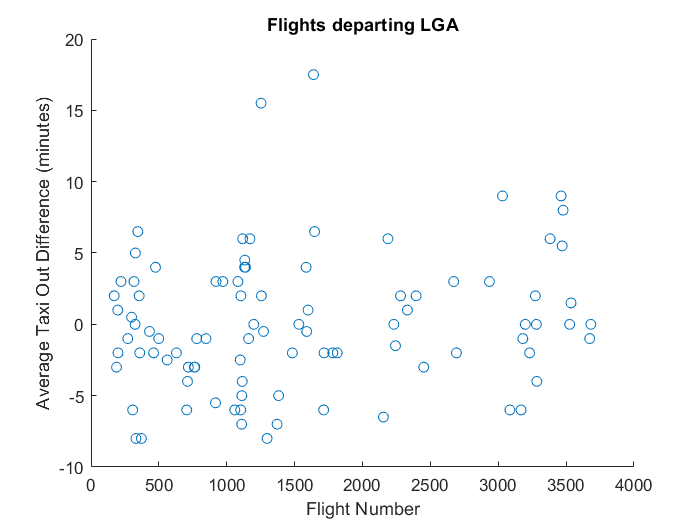

% First, chose an airport
originAirport = 'LGA';

% Take only flights originating from the chosen airport.
flightsAirport = flightsJoined(flightsJoined.ORIGIN == originAirport,:);

% Summarize the average taxi out times for each flight number from the chosen airport
temp = groupsummary(flightsAirport,"FLIGHT_NUMBER","median","TAXI_OUT_DIFF");
taxiOutSummary = sortrows(temp,"median_TAXI_OUT_DIFF","descend");

% Take only flights that happen at least once a day (you don't care about the once-a-month flights)
taxiOutSummary = taxiOutSummary(taxiOutSummary.GroupCount >= 27,:);

% Plot the results
scatter(taxiOutSummary.FLIGHT_NUMBER,taxiOutSummary.median_TAXI_OUT_DIFF)
title("Flights departing " + originAirport)
xlabel("Flight Number")
ylabel("Average Taxi Out Difference (minutes)")

Looks like two flights stand out above the rest with taxi out times of >15 minutes (for the default of LGA in February).

Want to find out where these flights are going to? You can use this summary table to look at just the information for one of these flights.

longestTaxiFlight = flightsAirport(flightsAirport.FLIGHT_NUMBER == taxiOutSummary.FLIGHT_NUMBER(1),:)

longestTaxiFlight = 28×24 table
        AIRLINE        TAIL_NUMBER    FLIGHT_NUMBER    ORIGIN    DESTINATION    SCHEDULED_DEPARTURE_TIME    ACTUAL_DEPARTURE_TIME    DEPARTURE_DELAY    TAXI_OUT    AIR_TIME    TAXI_IN    SCHEDULED_ARRIVAL_TIME    ACTUAL_ARRIVAL_TIME     ARRIVAL_DELAY    SCHEDULED_ELAPSED_TIME    ACTUAL_ELAPSED_TIME    DISTANCE    CANCELLED    CANCELLATION_CODE    DIVERTED    DAY_OF_MONTH    DELAYED    median_TAXI_OUT    TAXI_OUT_DIFF
    _______________    ___________    _____________    ______    

## Transforming Variables

For the last approach of feature generation, you will perform a complex example of transforming variables using the flights dataset.

Let's say you were trying to predict the flight duration for a new route between two airports that weren't previously connected with a direct flight. What would you do? This is a perfect job for a predictive model. In the following example, we've provided models that predict the duration of a flight between any two airports. This won't get into the specifics of how the models work here. For now, this example will just demonstrate why generating useful features is important for predictive modeling.

A flight's duration will be most dependent on the distance between its origin and destination. Here we've provided a custom function that creates a model from the flights dataset. This model takes distance as the input variable and tries to predict the scheduled elapsed time of each flight.

% Basic linear model predicting a flight's elapsed time from its distance.
% This is provided as an example, you do not need to understand how this works yet, as
% predictive modeling will be covered in a later course.
basicModel = fitlm(flights(:,["SCHEDULED_ELAPSED_TIME","DISTANCE"]),...
    'PredictorVar','DISTANCE','ResponseVar','SCHEDULED_ELAPSED_TIME');

% R-squared value
rSquaredBasic = basicModel.Rsquared.Ordinary

rSquaredBasic = 0.9553

The R-squared value is fairly high, meaning the model is a good fit. However, you can do even better.

To see why, look at this plot of flights at Boston Airport.

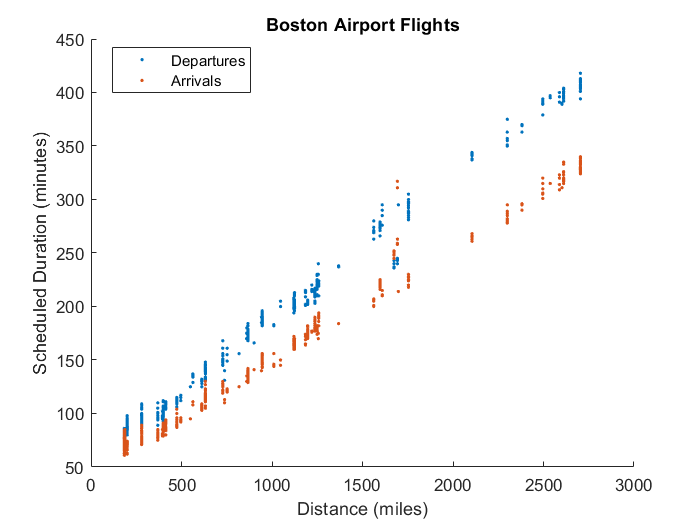

Notice how arriving flights take significantly less time than departing flights, even if they cover the same distance. Why is this?

Well, Boston is on the east coast, so most departures fly west while most arrivals fly east. Looks like the direction of a flight can have significant impact on its duration. This is because of the atmospheric jet stream, a fast moving west-to-east air current that can reach speeds of 200 km/h. Therefore, flights going west must fly against the jet stream, making them take longer than the same flight in the opposite direction.

So how can you account for the jet stream in your model? Looks like you'll need to figure out which direction they are flying in.

First, you'll need the geographic information for each flight's origin and destination, which can be merged from the airports data.

% Convert the AIRPORT variable to categorical so that it matches the key variable in the flights table
airports.AIRPORT = categorical(airports.AIRPORT);

% Join tables to capture the origin airport geographic data
flightsTemp = join(flightsOriginal,airports,"LeftKeys","ORIGIN","RightKeys","AIRPORT",...
    "RightVariables",["LATITUDE","LONGITUDE"]);

% Join tables again to capture the destination airport geographic data
flights = join(flightsTemp,airports,"LeftKeys","DESTINATION","RightKeys","AIRPORT",...
    "RightVariables",["LATITUDE","LONGITUDE"]);

% Rename the new variables for easier referencing
flights.Properties.VariableNames(end-3:end) = {'LATITUDE_ORIGIN', 'LONGITUDE_ORIGIN', 'LATITUDE_DESTINATION', 'LONGITUDE_DESTINATION'};

Next, you need a quantitative method to capture how much a flight is going east vs west. There are many ways to do this, but the one used here is to calculate the azimuthal angle of the flight path. This is the angle at the origin airport between the north pole and the destination airport. For example, a flight heading perfectly:

- North has an azimuthal angle of 0 degrees.

- East has an azimuthal angle of 90 degrees.

- West has an azimuthal angle of -90 (or 270) degrees.

You can use the `azimuth` function to calculate this angle from the latitude and longitude data for the origin and destination airports.

flights.AZIMUTH = azimuth(flights.LATITUDE_ORIGIN,flights.LONGITUDE_ORIGIN,...
    flights.LATITUDE_DESTINATION,flights.LONGITUDE_DESTINATION);

Finally, the jet stream effect means that you only need to quantify how much a flight is heading east vs west, not north vs south. You can capture this direction in a single number by taking the sine of the azimuthal angle. For example, a flight heading perfectly:

- North/South has an azimuthal sine of 0.

- East has an azimuthal sine of 1.

- West has an azimuthal sine of -1.

% Take the sine of the Azimuthal angle. The function, sind, takes degrees as input.
flights.SIN_AZIMUTH = sind(flights.AZIMUTH);

Next, we've provided for you a second more advanced model that predicts a flight's scheduled elapsed time using both distance and your newly generated feature, SIN_AZIMUTH, which captures the east/west direction of each flight.

% Basic linear model predicting a flight's elapsed time from its distance and direction.
% This is provided as an example, you do not need to understand how this works yet, as
% predictive modeling will be covered in a later course.
advancedModel = fitlm(flights(:,["SCHEDULED_ELAPSED_TIME","DISTANCE","SIN_AZIMUTH"]),...
    'interactions','ResponseVar','SCHEDULED_ELAPSED_TIME');

% R-squared value
rSquaredAdvanced = advancedModel.Rsquared.Ordinary

rSquaredAdvanced = 0.9849

This advanced model has an even higher R-squared value.

How do our two models compare in action? We've provided another custom function that allows you to visualize the results. On the plot below is listed:

- The prediction from our basic model that just uses the distance variable. 

- The prediction from our advanced model that uses both distance and the sine of the azimuth as input features.

- The average duration of flights on this route (if they are already connected by a direct flight).

To see the results, pick both an origin and destination airport. Now you can ask:

Which model is better?

And what is the estimated flight duration for airports that aren't currently connected with a direct flight?

originAirport = 'BOS';
destinationAirport = 'LAX';

% Custom function is found at end of this script.
% This is provided as an example, you do not need to understand how this works yet, as
% predictive modeling will be covered in a later course.
flightPredictions(originAirport, destinationAirport, basicModel, advancedModel, flights, airports);

Basic Model Prediction: 06:01:43
Advanced Model Prediction: 06:39:17
Average Duration: 06:37:00

## Custom Functions

*Feel free to explore this function. However, it is included to show the effects that good features have on model predictions. Predictive modeling will be covered in a later course.*

function flightPredictions(originAirport,destinationAirport,basicMdl,advancedMdl,flights,airports)
    originAirport = airports(airports.AIRPORT == originAirport,:);
    destinationAirport = airports(airports.AIRPORT == destinationAirport,:);
    
    distInput = distance(destinationAirport.LATITUDE,destinationAirport.LONGITUDE,...
        originAirport.LATITUDE,originAirport.LONGITUDE);
    distInput = deg2sm(distInput);
    sinAzInput = azimuth(originAirport.LATITUDE,originAirport.LONGITUDE,...
        destinationAirport.LATITUDE,destinationAirport.LONGITUDE);
    sinAzInput = sind(sinAzInput);
    flightDurBas = duration(minutes(predict(basicMdl,distInput)),"Format","hh:mm:ss");
    flightDurAdv = duration(minutes(predict(advancedMdl,[distInput sinAzInput])),"Format","hh:mm:ss");
    
    meanDur = duration(minutes(median(flights.SCHEDULED_ELAPSED_TIME(...
        flights.ORIGIN == originAirport.AIRPORT(1)...
        & flights.DESTINATION == destinationAirport.AIRPORT(1)))),"Format","hh:mm:ss");
    if meanDur ~= meanDur
        meanDur = "No Flights";
    end
    
    fprintf("Basic Model Prediction: " + string(flightDurBas))
    fprintf("\nAdvanced Model Prediction: " + string(flightDurAdv))
    fprintf("\nAverage Duration: " + string(meanDur))
end
